# Predictive Control for Cobot Safety

*Could add in a short introductory description of the aims of the project and such*

## Robot Plant and Initial Conditions

clc;

Load the KINOVA Gen 3 robot manipulator multibody model and rigid body tree.

[robotRBT, robotInformation] = loadrobot("kinovaGen3", DataFormat="column", Gravity=[0 0 -9.81]);

Define key robot parameters that will be used further on. The quantity of joints and the end-effector (tool) element of the rigid body tree.

joint_qty = numel(homeConfiguration(robotRBT));
endEff = 'EndEffector_Link';

Prepare inverse kinematic equations to compute robot configurations given end-effector poses.

robot_InverseKinematics = inverseKinematics("RigidBodyTree", robotRBT);
robot_InverseKinematics.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

Define initial and final trajectory task-space coordinates. The initial position may be given as a complete robot configuration while the final position is a desired end-effector pose (other joint positions in the task-space are irrelevant).

qInit = [0 0 0 0 0 0 0]'*pi/180; % initial joint configuration in radians
taskInit = getTransform(robotRBT, qInit, endEff); % initial transformation matrix of task
coordStart = taskInit(1:3, 4); % initial task-space end-effector coordinates XYZ
xInit = [qInit', zeros(1, joint_qty)]; % initial robot state [q, dq]

taskEnd = trvec2tform([0.6 0.4 0.3])*axang2tform([0 1 0 pi]); % final task-space end-effector coordinates XYZ
anglesEnd = rotm2eul(taskEnd(1:3, 1:3), "XYZ"); % final task-space end-effector rotational coordinates [phi theta psi]
poseEnd = [taskEnd(1:3, 4); anglesEnd']; % final pose vector [X Y Z phi theta psi]

## Static and Dynamic Obstacles

Generate static obstacles that represent elements of the environment.

safety_dist = 0.1;
staticObstacleGeneration;

Define primary task-driven waypoints for the dynamic obstacle. In this case, the representative collaborative partner and obstacle will be a robot model aiming to reach the waypoints with an end-tool.

task_waypoints = [0.6 0.3 0.3 0 1 0 pi;     % PosX PosY PosZ RotX RotY RotZ rotationAngle
    0.4 -0.1 0.3 0 1 0 pi;
    0.2 -0.2 0.4 0 1 0 pi/2; 
    0.2 -0.2 0.7 0 1 0 pi/2;
    0.4 -0.3 0.8 0 1 0 pi/2;
    0.2 -0.4 0.7 0 1 0 pi/2;
    0.2 -0.4 0.4 0 1 0 pi;
    0.4 -0.5 0.3 0 1 0 pi;
    0.5 0.1 0.3 0 1 0 pi;
    0.6 0.3 0.3 0 1 0 pi];

Generate dynamic obstacle representing the collaborative element to the plant. This model will represent a human working alongside the KinovaGen3 robot.

[obst_robot, ~] = loadrobot("kinovaGen3", DataFormat="column", Gravity=[0 0 -9.81]);

Generate the task trajectory for the obstacle robot to follow desired waypoints during the simulation.

dynamicObstacleTrajectoryGeneration;

## Initial Visualization

Generate a 3D graphical visualization of the initial task-space environment, robot configurations, task trajectory of the obstacle robot, and start and end goals.

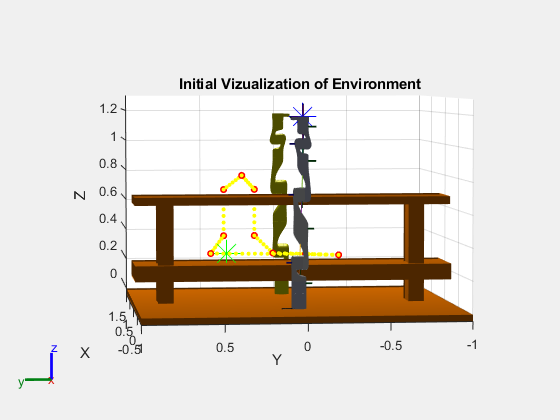

generateTaskEnvironment(robotRBT, qInit, coordStart, poseEnd, staticObst, obst_robot, task_waypoints, ...
    waypoints, 'Robot and Obstacle Conditions', 'Initial Vizualization of Environment')

## Design: PID Control

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

Generate visualizations for the initial environment objects.

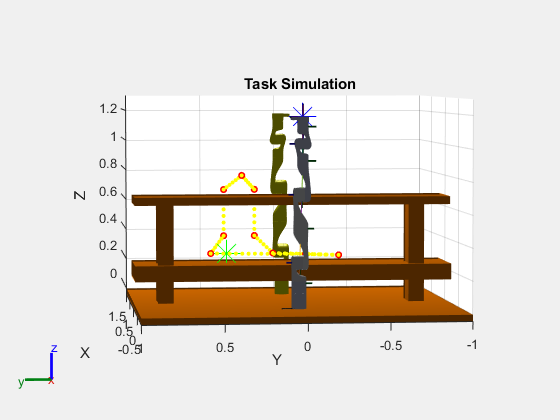

generateTaskEnvironment(robotRBT, qInit, coordStart, poseEnd, staticObst, obst_robot, task_waypoints, ...
    waypoints, 'Task Simulation', 'Task Simulation', true);

Simulate task dynamics and control responses of the obstacle robot and robot of interest.

%runSimulationLoop;

## Design: Linear MPC

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

## Design: Non-linear MPC

The state equation defines a model capable of computing state predictions based on the relationship between current joint positions $q
$ and  velocities $\dot{q}$ subject to control input acceleration $\ddot{q}$.

- Output: $\dot{x} = [\dot{q}, \ddot{q}]$

- States: $x = [q, \dot{q}]$

- Input: $u = \ddot{q}$

Hence, the state equation is modelled as:


$$\dot{\mathit{\mathbf{x}}} =\mathbf{Ax}+\mathit{\mathbf{Bu}}$$


generateNMPC;

### Closed-Loop Trajectory Planning

obstacles = staticObst;
% obst_bodies = obst_robot.Bodies;
% 
% for i=1:length(obst_bodies)
%     if ~isempty(obst_bodies{i}.Collisions)
%         obst_transform = getTransform(obst_robot, robotStateAll(1,1:7)', obst_bodies{i}.Name);
%         for j=1:length(obst_bodies{i}.Collisions)
%             collision_obj = obst_bodies{i}.Collisions{j};
%             collision_obj.Pose = obst_transform * obst_bodies{i}.Collisions{j}.Pose;
% 
%             obstacles{end+1} = collision_obj;
%         end
%     end
% end

Simulation initial conditions

maxIteration = 50;
uInit = zeros(1, joint_qty);
mv = uInit;
time = 0;
goalReached = false;

Initialize data matrices

positions = zeros(joint_qty, maxIteration);
positions(:,1) = xInit(1:joint_qty)';

velocities = zeros(joint_qty, maxIteration);
velocities(:,1) = xInit(joint_qty+1:end);

accelerations = zeros(joint_qty, maxIteration);
accelerations(:,1) = uInit';

timeStep = zeros(1, maxIteration);
timeStep(:,1) = time;

x = xInit;
options = nlmpcmoveopt;
for iteration=1:maxIteration
    disp(['Calculating control at timestep: ', num2str(iteration)])
    
    % optimize next trajectory point
    [mv, options, info] = nlmpcmove(n_mpc, x, mv, [], [], options)

    % check for failed trajectory generations
    if info.ExitFlag < 0
        disp('Failed to compute a feasible trajectory. Aborting...')
        break
    end

    % update states and time
    x = info.Xopt(2,:);
    time = time + n_mpc.Ts;

    % log trajectory
    positions(:,iteration+1) = x(1:joint_qty)';
    velocities(:,iteration+1) = x(joint_qty+1:end)';
    accelerations(:,iteration+1) = info.MVopt(2,:)';
    timeStep(iteration+1) = time;

    % check if at desired pose
    tolerance = 0.03;
    jointFinal_i = info.Xopt(2,1:joint_qty);
    taskFinal_i = getTransform(robotRBT, jointFinal_i', endEff);
    anglesFinal_i = rotm2eul(taskFinal_i(1:3,1:3), "XYZ");
    poseFinal_i = [taskFinal_i(1:3,4);anglesFinal_i'];
    e_end = abs([poseEnd(1:3)-poseFinal_i(1:3); angdiff(poseFinal_i(4:6), poseEnd(4:6))]);
    flag = ones(size(Qt,1), 1) & diag(Qt);

    if all(e_end(flag) < tolerance)
        disp('Target configuration reached.')
        break
    end

    % update obstacle pose
    obst_currTrans = getTransform(obst_robot, robotStateAll(iteration+1,1:7)', endEff)
    %obstacles = [staticObst, {obst_currTrans}];

    n_mpc.Optimization.CustomIneqConFcn = @(X,U,e,data) inequalityConstraint(X,data,safety_dist,obstacles,robotRBT);
    n_mpc.Jacobian.CustomIneqConFcn = @(X,U,e,data) jacobianInequalityConstraint(X,data,obstacles,robotRBT);
end

Calculating control at timestep: 1


Slack variable unused or zero-weighted in your custom cost function.
All constraints will be hard.


mv =      0
     0
     0
     0
     0
     0
     0


options =   nlmpcmoveopt with properties:

    OutputWeights: []
        MVWeights: []
    MVRateWeights: []
        ECRWeight: []
        OutputMin: []
        OutputMax: []
         StateMin: []
         StateMax: []
            MVMin: []
            MVMax: []
        MVRateMin: []
        MVRateMax: []
         MVTarget: []
       Parameters: {}
               X0: [5×14 double]
              MV0: [5×7 double]
           Slack0: 0

  Show all accessible properties of nlmpcmoveopt


info = struct with fields:
         MVopt: [6×7 double]
          Xopt: [6×14 double]
          Yopt: [6×7 double]
          Topt: [6×1 double]
         Slack: 0
      ExitFlag: 0
    Iterations: 5
          Cost: 36.3577


### Joint-Space Simulation

### Final Visual Simulation